# **涡流测距原理演示**

**        与上一小节类似，根据Dodd-Deeds 模型，可以得到涡流线圈阻抗变化量的积分解析表达式。**


$$\begin{array}{l}
\Delta Z=\frac{j\pi \omega \mu_0 N_c^2 }{(r_2 -r_1 )^2 (z_2 -z_1 )^2 }\int_0^{\infty } \frac{\chi^2 (\lambda_0 r_1 ,\lambda_0 r_2 )}{\lambda_0^6 }(e^{-\lambda_0 z_1 } -e^{-\lambda_0 z_2 } )^2 R(\lambda_0 )d\lambda_0 \\
\;\;\;\;\;\;\;=K\int_0^{\infty } \frac{I^2 }{\lambda_0^6 }P^2 R(\lambda_0 )d\lambda_0 
\end{array}$$


**其中，**


$$K=\frac{j\omega \pi \mu_0 N^2 }{(z_2 -z_1 )^2 (r_2 -r_1 )^2 }$$



$$P\left(\lambda_0 \right)={\left(e^{-\lambda_0 I_1 } -e^{-\lambda_0 I_2 } \right)}^2$$



$$R\left(\lambda_0 \right)=\frac{\left(\lambda_1 +\lambda_0 \right)\left(\lambda_1 -\lambda_0 \right)-\left(\lambda_1 +\lambda_0 \right)\left(\lambda_1 -\lambda_0 \right)e^{2\lambda_1 d} }{\left(\lambda_0 -\lambda_1 \right)\left(\lambda_1 -\lambda_0 \right)+\left(\lambda_1 +\lambda_0 \right)\left(\lambda_1 +\lambda_0 \right)e^{2\lambda_1 d} }$$



$$I\left(\lambda_0 \right)=\int_{\lambda_0 r_1 }^{\lambda_0 r_2 } \textrm{xJ}\left(x\right)\textrm{dx}$$



$$\lambda_1 =\sqrt{\lambda_0^2 +j\omega \sigma \mu }$$


**        本节运用梯形积分法计算，并展示线圈阻抗变化量随着提离距离变化的变化曲线。**

- **定义参数**

pr1=3.15e-3; % 线圈内径
pr2=5.62e-3; % 线圈外径
Turns=850;  % 线圈匝数
liftoffmax=1.5e-3;% 提离距离最大值
q=0.3e-3:0.3e-3:liftoffmax;
height=2.94e-3; % 探头的长度（线圈的厚度）
sigma=18.5;%金属板电导率
sigma=sigma*1.0e6;
d=0.004;
ur=1;
mu0=4*pi*1.0e-7; %真空磁导率
frq=1.0e3;       % 探测频率
omig=2*pi*frq;   % 角频率
K=(1i*omig*pi*mu0*Turns^2)/((height)^2*(pr2-pr1)^2); % 系数K
%积分运算的参数
upper=6000;
h=5;
lambd=h:h:upper;

- **计算线圈阻抗随着金属厚度变化的曲线**

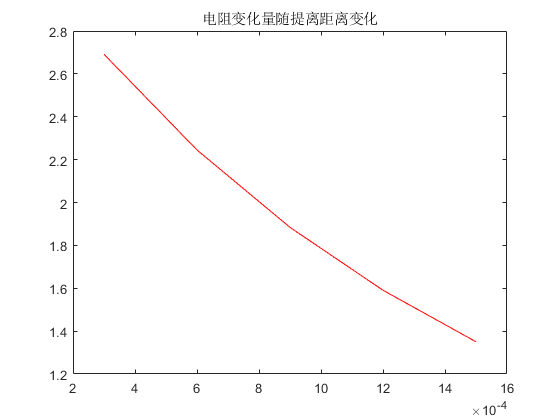

Results=[];

I_lambd=I(lambd,pr1,pr2);%积分参数、内径、外径
%P_lambd=P(lambd,liftoff,height);%积分参数、提离高度、线圈高度
R_lambd=R(lambd,omig,sigma,mu0,d,ur);%积分参数、角频率、电导率、磁导率、材料厚度

liftoffNum=length(q);
for liftoff=1:liftoffNum
    P_lambd=P(lambd,q(liftoff),height);
    fun=P_lambd.*R_lambd.*I_lambd;
    temp=sum(fun);
    DZ=K*(temp*2-fun(1)-fun(end))*h/2;
    clear temp fun P_lambd;
    Results=[Results DZ];
end
figure
plot(q,real(Results),'r')
title('电阻变化量随提离距离变化')
set(gcf,'Visible','on');   	    %强制图片弹出显示

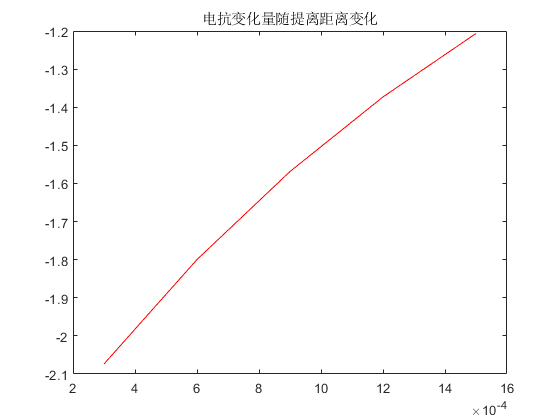

figure
plot(q,imag(Results),'r')
title('电抗变化量随提离距离变化')
set(gcf,'Visible','on');   	    %强制图片弹出显示

Results

Results =    2.6914 - 2.0737i   2.2448 - 1.7997i   1.8841 - 1.5687i   1.5906 - 1.3730i   1.3503 - 1.2064i


- **求解R**

function R_lambd=R(lambd,omig,sigma,mu0,d,ur)
    R_lambd=-1;
    lambd1=sqrt(lambd.^2+1i*omig*sigma*mu0);
    
    temp_a=(lambd.^2*ur-lambd1.^2).*exp(2*lambd*d);
    temp_b=(lambd1.^2-lambd.^2*ur);
    temp_c=(lambd1+lambd*ur).^2.*exp(2*lambd*d);
    temp_d=(lambd1-lambd*ur).^2;
        
    temp=(temp_a+temp_b)./(temp_c-temp_d);
    R_lambd=[R_lambd temp];
end

- **求解I**

function Pinte=FirBessel(x)
    Pinte=x.*besselj(1,x);       
end
function I_lambd=I(lambd,pr1,pr2)
    I_lambd=0;
    LoopNum=length(lambd);
    for k=1:LoopNum
        % 以自适应 Simpson 积分法计算数值积分
        % 将lambd0的-6次方项加入到I的计算中
        temp=quad(@FirBessel,pr1*lambd(k),pr2*lambd(k))^2/lambd(k)^6;
        I_lambd=[I_lambd temp];
    end
end

- **求解P**

function P_lambd=P(lambd,liftoff,height)
    Z1=liftoff;%提离
    Z2=liftoff+height;%提离+线圈高
    P_lambd=(Z2-Z1)^2;
    temp=(exp(-lambd*Z1)-exp(-lambd*Z2)).^2;
    P_lambd=[P_lambd temp];
end

- **参考文献**

**        [1] 范孟豹. 多层导电结构电涡流检测的解析建模研究[D].浙江大学,2009.**

**        [2] Dodd C V, Deeds W E. Analytical solutions to eddy‐current probe‐coil problems[J]. Journal of applied physics, 1968, 39(6): 2829-2838.**